# Gastrointestinal Cancer Detection - [tutorial](https://blogs.mathworks.com/deep-learning/2019/07/24/deep-learning-for-medical-imaging/)

The image referenced in the tutorial no longer exists, so new images were found with cases of Cancer Tissue.

## Initialize

img_path = "./images/task_2/";

% Image 1
img1 = {0};
img1_path = img_path + "image_1/e9e1cd0e-b6a1-47b5-991d-390d1d3cf28a/TCGA-B9-4116-01A-01-BS1.2e62bc60-29f4-48b9-8fd6-a58b118adf9c.svs";
nrOfImgs_1 = 4; % multi-image file where each image is diff size
for i=1:nrOfImgs_1
    img1{i} = imread(img1_path, i);
    fprintf("Read image layer %d/%d\n", i, nrOfImgs_1);
end

Read image layer 1/4
Read image layer 2/4
Read image layer 3/4
Read image layer 4/4



% Image 2
img2 = {0};
img2_path = img_path + "image_2/6e63430a-4a44-4ba8-a1f9-f24871c8f08a/TCGA-B1-A47M-11A-01-TS1.1E82A92A-DEB4-4690-9D63-52F9EAE59D0D.svs";
nrOfImgs_2 = 4; % multi-image file where each image is diff size
for i=1:nrOfImgs_2
    img2{i} = imread(img2_path, i);
    fprintf("Read image layer %d/%d\n", i, nrOfImgs_2);
end

Read image layer 1/4
Read image layer 2/4
Read image layer 3/4
Read image layer 4/4


## Read Images

The base image (channel 1) is so big that we cannot even look at it... but let's look at some of the smaller images instead.

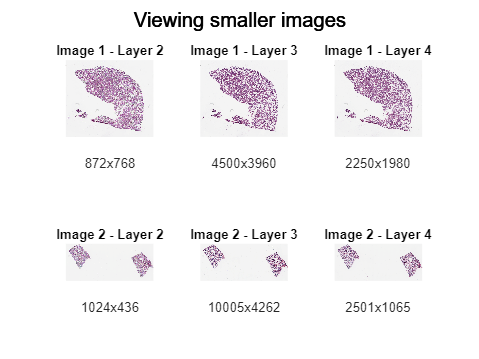

figure;

% Image 1
img1_Info = imfinfo(img1_path); % get the metadata
subplot(2,3,1); imshow(img1{2}); title("Image 1 - Layer 2"); xlabel(num2str(img1_Info(2).Width) + "x" + num2str(img1_Info(2).Height));
subplot(2,3,2); imshow(img1{3}); title("Image 1 - Layer 3"); xlabel(num2str(img1_Info(3).Width) + "x" + num2str(img1_Info(3).Height));
subplot(2,3,3); imshow(img1{4}); title("Image 1 - Layer 4"); xlabel(num2str(img1_Info(4).Width) + "x" + num2str(img1_Info(4).Height));

% Image 2
img2_Info = imfinfo(img2_path); % get the metadata
subplot(2,3,4); imshow(img2{2}); title("Image 2 - Layer 2"); xlabel(num2str(img2_Info(2).Width) + "x" + num2str(img2_Info(2).Height));
subplot(2,3,5); imshow(img2{3}); title("Image 2 - Layer 3"); xlabel(num2str(img2_Info(3).Width) + "x" + num2str(img2_Info(3).Height));
subplot(2,3,6); imshow(img2{4}); title("Image 2 - Layer 4"); xlabel(num2str(img2_Info(4).Width) + "x" + num2str(img2_Info(4).Height));

sgtitle("Viewing smaller images");

## Setting up Alexnet

figure;
net = alexnet; % load an alexnet which is pretrained on ImageNet

allImages = imageDatastore(img_path + 'train_images/', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

Use a different ratio for the data split-up than what is mentioned in the blog:

35% training, 30% validation, 35% test

*"Split into three sets: 40% training, 20% validation, 40% test"*

[training_set, validation_set, testing_set] = splitEachLabel(allImages,.35,.30,.35); %.4,.2,.4);

### Network modification

Modify the network by **removing the last three layers**. We will **replace these layers with new layers** for our custom classification.

layersTransfer = net.Layers(1:end-3);

Display Labels

training_labels = categories(training_set.Labels);
numClasses = numel(training_labels)

numClasses = 9

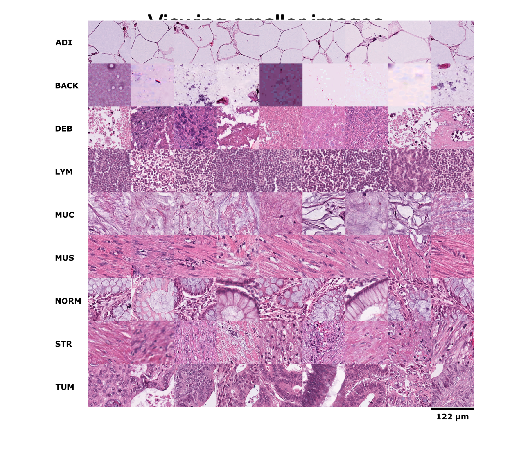

labels_desc = ["Adipose Tissue (fat)", "Background (no tissue)", "Debris", ...
    "Lymphocytes", "Mucus", "Muscle", "Normal Mucosa", "Stroma", "Tumor Epithelium"];

figure;
imshow(imread(img_path + "feature_patterns.png"));


disp("Output Categories");

Output Categories


for i=1:size(training_labels, 1)
    disp("  " + training_labels{i} + " - " + labels_desc(i));
end

  ADI - Adipose Tissue (fat)
  BACK - Background (no tissue)
  DEB - Debris
  LYM - Lymphocytes
  MUC - Mucus
  MUS - Muscle
  NORM - Normal Mucosa
  STR - Stroma
  TUM - Tumor Epithelium


We **merge the layers**, and **set the weight and bias learning rate** for the last fully connected layer 'fc'

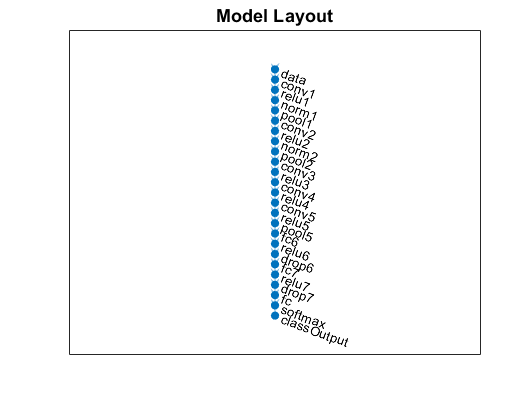

%weight_lr = 1;
%bias_lr = 1;

figure;

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'Name', 'fc','WeightLearnRateFactor', 1,'BiasLearnRateFactor', 1)
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')];

lgraph = layerGraph(layers);
plot(lgraph); title("Model Layout");

### Modify Training Parameters

We now modify the training set and training options. The training set must be resized to fit the input size expected by the network.

imageInputSize = [227 227 3];
augmented_training_set = augmentedImageDatastore(imageInputSize, training_set)

augmented_training_set =   augmentedImageDatastore with properties:

             NumObservations: 2512
                       Files: {2512×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



resized_validation_set = augmentedImageDatastore(imageInputSize, validation_set);
resized_testing_set = augmentedImageDatastore(imageInputSize, testing_set);

Set the training options, including plotting the training progress as the network trains.

opts = trainingOptions('sgdm', ...
    'MiniBatchSize', 64,... % mini batch size, limited by GPU RAM, default 100 on Titan, 500 on P6000
    'InitialLearnRate', 1e-4, ... % fixed learning rate
    'L2Regularization', 1e-4,... % optimization L2 constraint
    'MaxEpochs', 10,... % max. epochs for training, default 3 / 15
    'ExecutionEnvironment', 'gpu',...% environment for training and classification, use a compatible GPU
    'ValidationData', resized_validation_set,...
    'Plots', 'training-progress')

opts =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
            ExecutionEnvironment: 'gpu'
                      WorkerLoad: []
                       OutputFcn: []
                           Plots: 'training-progress'
     

## Training

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |        6.25% |        7.98% |       4.8312 |       3.5839 |      1.0000e-04 |
|       2 |          50 |       00:00:53 |       76.56% |       88.64% |       0.6896 |       0.3249 |      1.0000e-04 |
|       3 |         100 |       00:01:33 |       90.62% |       92.76% |       0.2835 |       0.2159 |      1.0000e-04 |
|       4 |         150 |       00:02:13 |       95.31% |       94.57% |       0.2051 |       0.1686 |      1.0000

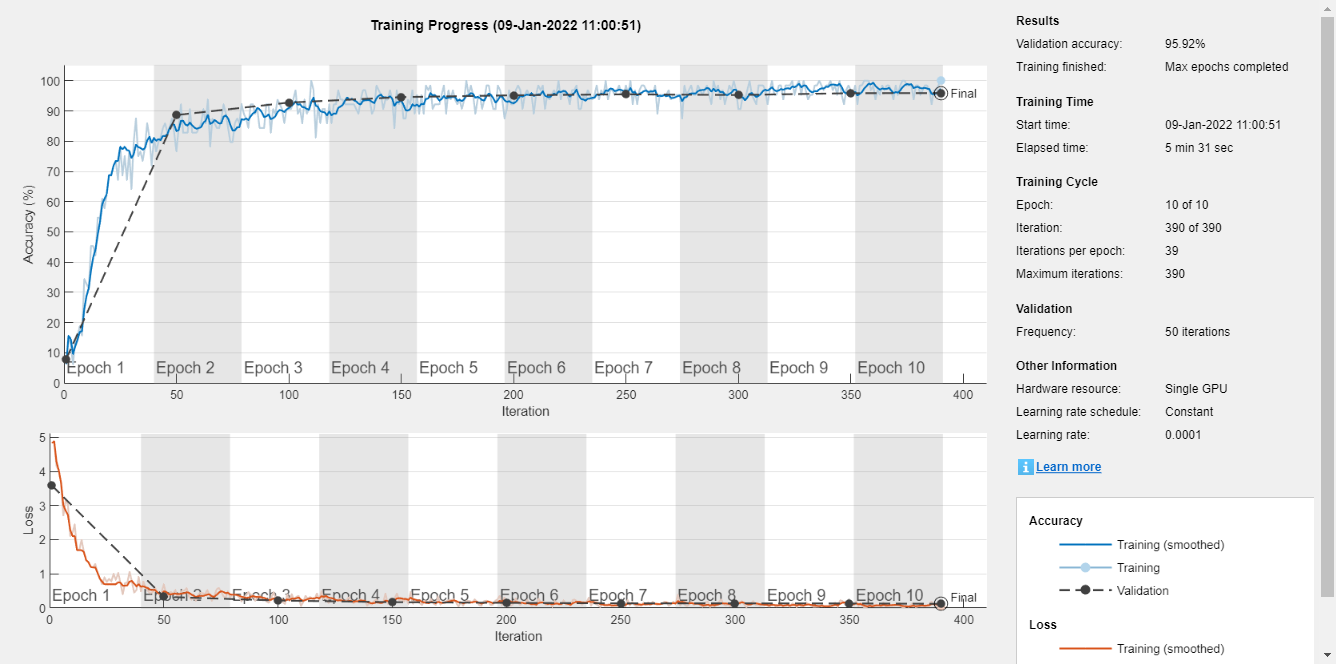

net = trainNetwork(augmented_training_set, lgraph, opts);

## Testing and Prediction

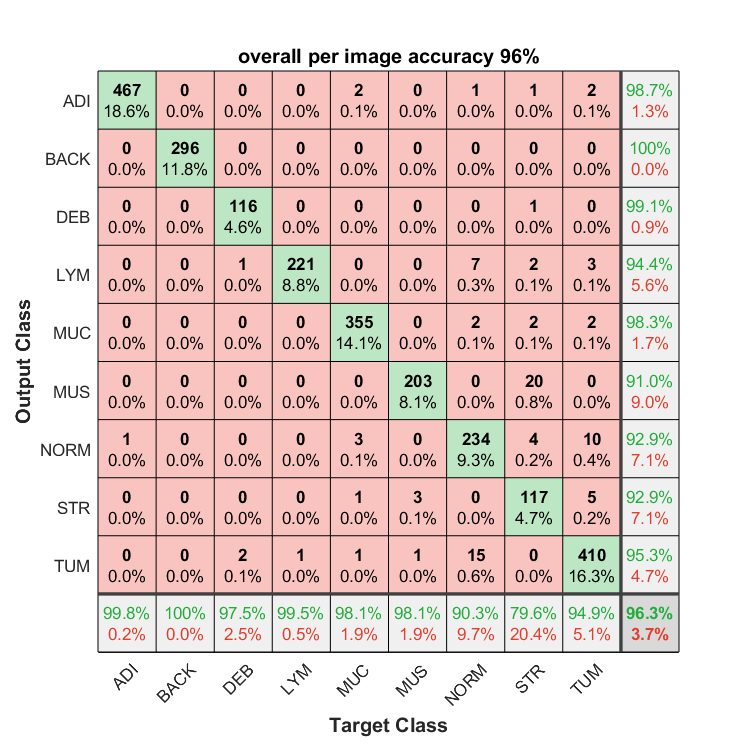

[predLabels,predScores] = classify(net, resized_testing_set, 'ExecutionEnvironment','gpu');

plotconfusion(testing_set.Labels, predLabels)
PerItemAccuracy = mean(predLabels == testing_set.Labels);
title(['overall per image accuracy ',num2str(round(100*PerItemAccuracy)),'%'])

## Questions

**Explain in your own words the steps followed, modifications made and the results achieved.**

- Firstly, the svg **image(s) needed to be read along with its labels** as a Datastore data type compatible with the deep learning module of Matlab.

- The **dataset was split** into chunks to each represent which images to be used for training, validation and testing.

- Then we **setup the network model** by defining its **layers** (layers made of "neural nodes" and the connectivity between them) and **parameters** (bias + weight to be added to the learning rate)

- Next up, the model is restricted by what image size is accepted to pass through, thus the images need to be resized (or augmented) before using them. Images could potentially also be augmented during the process of a CNN if needed to avoid issues such as overfitting.

- Lastly, the model started to train, giving accuracy and error loss results for each and all epochs (batches).

**Show clearly your test images and results. What is the accuracy you have achieved, for your subset of images? Compare with the results in the blog.**

- At first, with just the dataset split difference, the training comes back with **91.4% accuracy (3.5% decrease) and 8.6% loss (3.5% higher)** than the blog's results.

- I tried to increase the learning rate by 2 decimal points, which led to an error in training = "weights are NaN". After googling, I found out that this can happen if the data includes large regression response values, stating that lowering the learning rate is one solution to the problem.

- Therefore, I decreased the rate to what it was before and then even lower than that but I kept getting the error regardless. It seems to only work when it feels like it.

- Then, I kept the lower rate and lowered the number of max epochs, especially since it seems that it doesn't take long for the accuracy to reach 80%, having the loss decrease below 1 within the first epoch. This ended up giving me better results than the first time AND the blog, **concluding at 96.3% acc (1.4% increase) and 3.7% loss (1.4% decrease)**. 

**Analyse when and why misclassification occurs.**

- The feature patterns in this field can have extremely slight differences between them, as tissue color and texture can be easily picked off when it's something like the background and a tumor tissue area, BUT it can even be hard for humans to distringuish between muscle and stroma tissue.

**Reflection:**

**What was the most difficult part?**

- Understanding how to modify the layers of the network and for what desired purpose. It's also generally hard to distringuish what is affected and in what magnitude when there is not a lot of prior experience.

**Do you see any limitation of the transfer learning?**

- Apart from an obvious time consuming part, transfer learning can be perfect for deeply researched fields with a set amount of obtainable information, but lacks the flexibility of teaching the model unknown or unpredicted patterns and features.

**How would you improve the results (suggest modifications to existing solution or a completely new approach)?**

- If I could I would spend time designing to add another sub-section in the system for not so recognized feature patterns, such that it would allow for 'unknown' or 'not so sure' categories to be set to a subset (or cluster) of images. These images could then have their own individualized process using a blind approach. If possible, also create and add a tool/section that recognizes new patterns that inserts them into the pattern sheet once popular enough.